% AAE 666 HW1 Exercise-9
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2021-Spring\AAE666\matlab\hw1';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

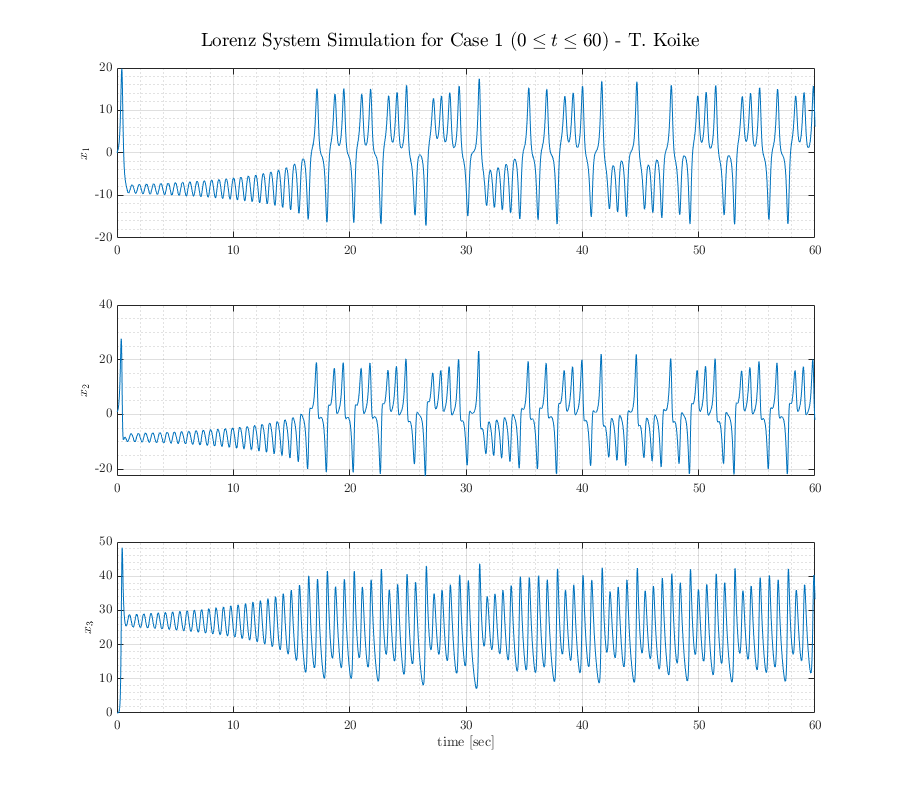

% Constants
sigma = 10;
b = 8/3;
r = 28;

% Case 1 
% - Initial conditions 
x1_0 = 0;
x2_0 = 1;
x3_0 = 0;

% - Simulate 
simout = sim("lorenzSystem.slx");

% - Data rendering 
x1 = simout.x1sim.signals.values;
x2 = simout.x2sim.signals.values;
x3 = simout.x3sim.signals.values;
t  = simout.tout;

% - Plot 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    subplot(3,1,1)
    plot(t, x1)
    grid on; grid minor; box on;
    ylabel('$x_1$')
    subplot(3,1,2)
    plot(t, x2)
    grid on; grid minor; box on;
    ylabel('$x_2$')
    subplot(3,1,3)
    plot(t, x3)
    grid on; grid minor; box on;
    ylabel('$x_3$')
    xlabel('time [sec]')
    title_string = 'Lorenz System Simulation for Case 1 ($0\leq t \leq 60$) - T. Koike';
    sgtitle(title_string)
saveas(fig, 'ex9_case1.png')

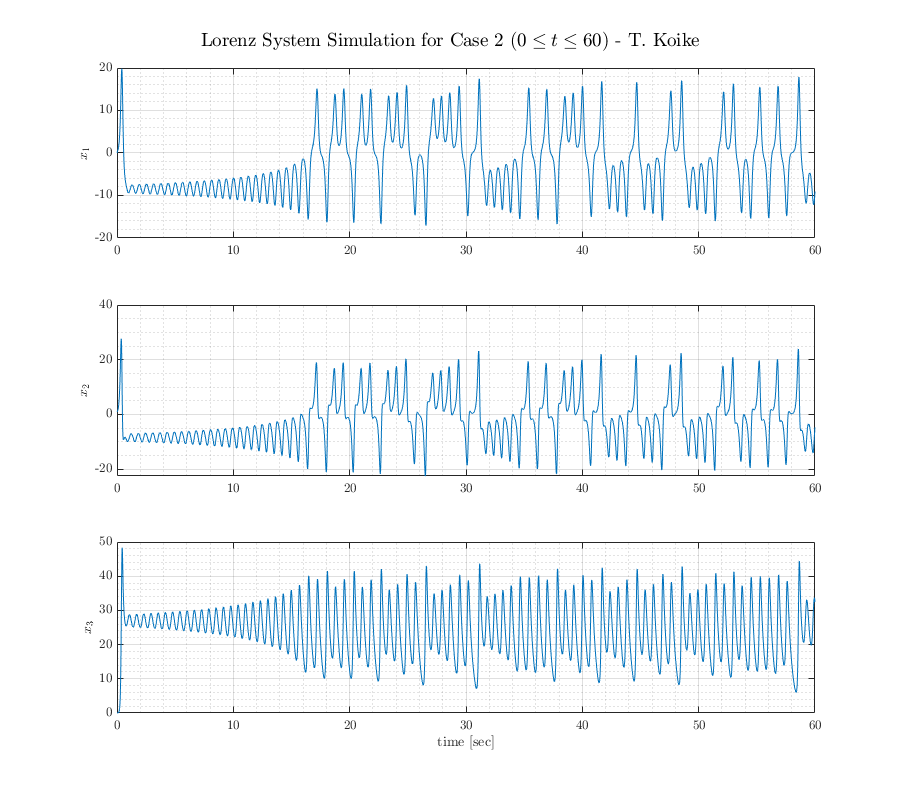

% Case 2 
% - Initial conditions 
x1_0 = 0;
x2_0 = 1+eps;
x3_0 = 0;

% - Simulate 
simout = sim("lorenzSystem.slx");

% - Data rendering 
x1 = simout.x1sim.signals.values;
x2 = simout.x2sim.signals.values;
x3 = simout.x3sim.signals.values;
t  = simout.tout;

% - Plot 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    subplot(3,1,1)
    plot(t, x1)
    grid on; grid minor; box on;
    ylabel('$x_1$')
    subplot(3,1,2)
    plot(t, x2)
    grid on; grid minor; box on;
    ylabel('$x_2$')
    subplot(3,1,3)
    plot(t, x3)
    grid on; grid minor; box on;
    ylabel('$x_3$')
    xlabel('time [sec]')
    title_string = 'Lorenz System Simulation for Case 2 ($0\leq t \leq 60$) - T. Koike';
    sgtitle(title_string)
saveas(fig, 'ex9_case2.png')